# Grid of cells (2DOF)

clear; close all; clc;
set_env;
addpath("2DOF\");
load('2DOF\cell_2dof_pstrain.mat')
load('2DOF\cell_2dof_pstress.mat')
load('2DOF\res_2dof_pstrain.mat')

% Data --------------------------------------------------------------
% Constants

% Symbolic variables ------------------------------------------------
% Data
syms nu Y_p epsilon_p epsilon_f EBD_p EBD_f l_0 w_0 tp_0 tf_0 xi_0 x l_c
syms d P_t Vtank f
syms p_atm T_std gamma_air rhostd_air c_v c_p
% New variables
syms T(x_t) p(x_t) rho_0 Vc_0 T_0 Vf_tot

% Physical quantities
syms V


## Single cell quantites

pstrain = sstrain2(pstrain_2dof, 'PSTRAIN');
Vol_fcell = 2 * pstrain.Vol_f; 
Vol = 2 * pstrain.Vol;
Uel_xmaxcell = 2 * res_2dof_pstrain{end}.Uel_xmax;
uel_xmaxcell = 2 * res_2dof_pstrain{end}.uel_xmax;
F_cell = 2 * res_2dof_pstrain{end-1}.int_F;
x_range_ref = res_2dof_pstrain{end}.x_range_ref;
C = 2 * pstrain.C1;


x_min = x_range_ref(1);
x_max = double(0.3 * sdata2(l_0));
x_range = x_min:1e-5:x_max;
x_range_norm = double(x_range / sdata2(l_0));
Uel_xmax = interp1(x_range_ref, Uel_xmaxcell, x_range);
uel_xmax = interp1(x_range_ref, uel_xmaxcell, x_range);
F_cell = interp1(x_range_ref, F_cell, x_range);
max_uel = max(uel_xmax);

myfig(1, "U_{el} and u_{el}");

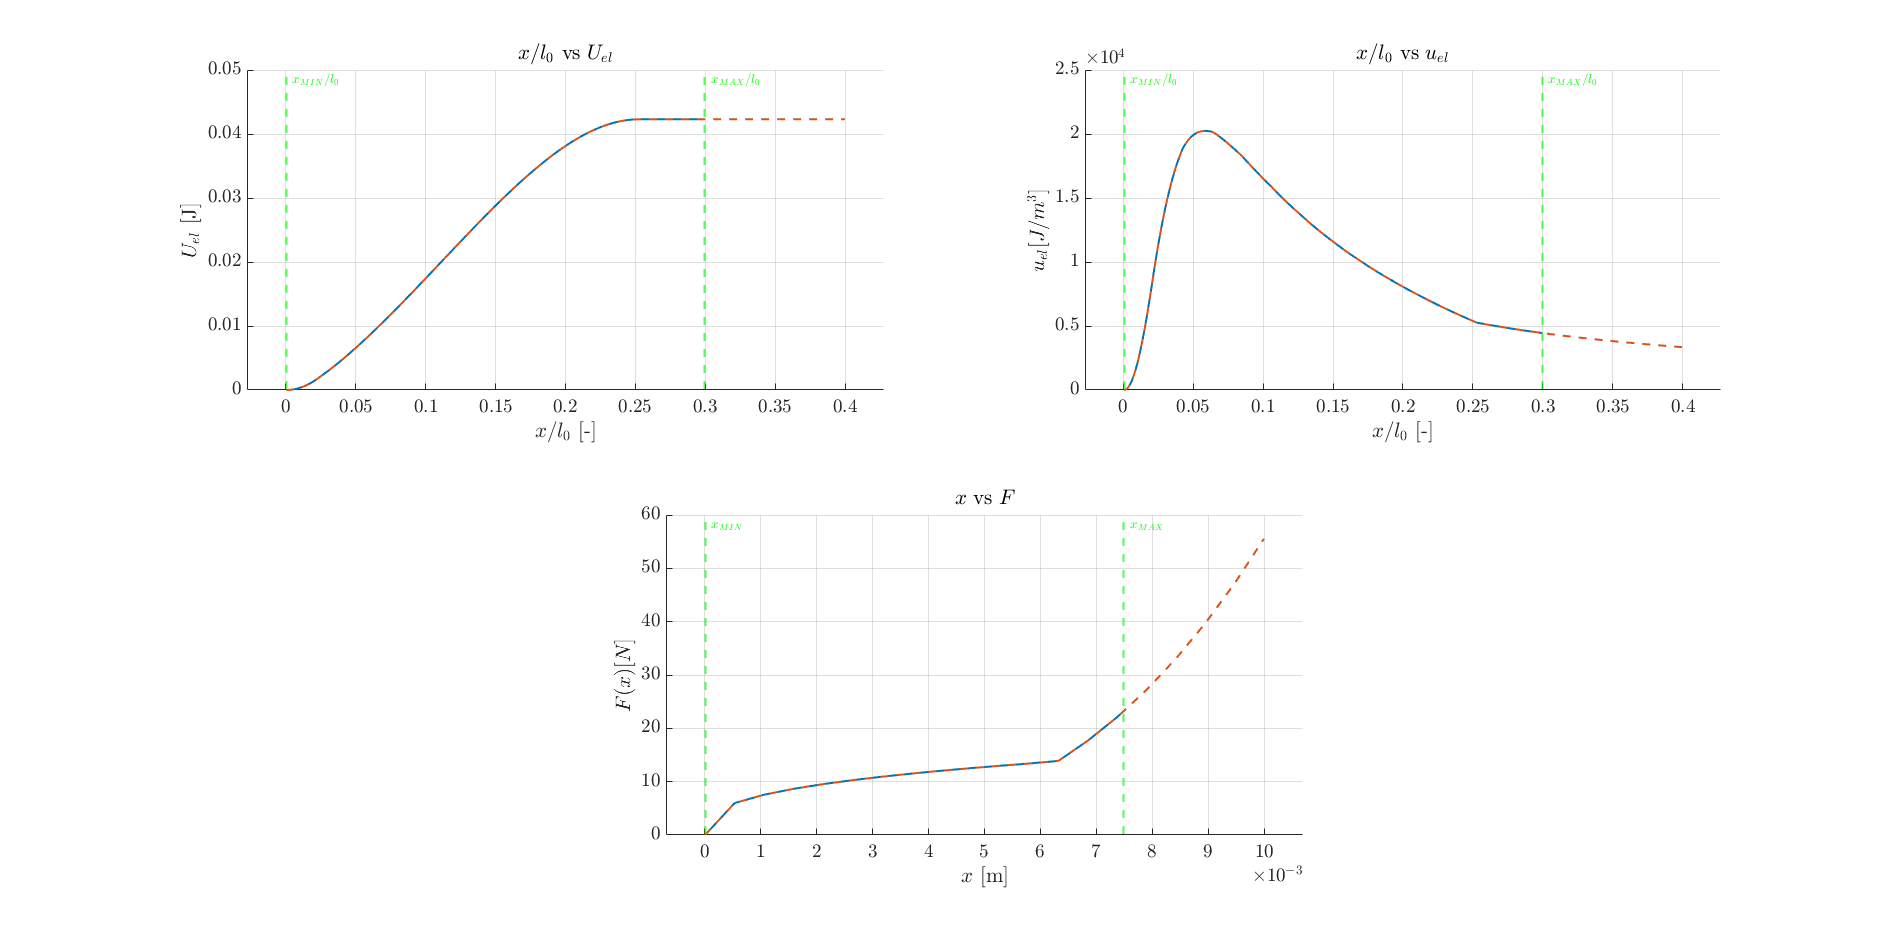

subplot(2,2,1); hold on
plot(x_range_norm, Uel_xmax)
plot(x_range_ref / sdata2(l_0), 2 * res_2dof_pstrain{end}.Uel_xmax, '--')
plot_xminmax(x_range_norm(1), x_range_norm(end), "$x_{MIN} / l_0$", "$x_{MAX} / l_0$")
addlabels("$x / l_0$ [-]", "$U_{el}$ [J]", "$x / l_0$ vs $U_{el}$")
xlim("padded")

subplot(2,2,2); hold on
plot(x_range_norm, uel_xmax)
plot(x_range_ref / sdata2(l_0), 2 * res_2dof_pstrain{end}.uel_xmax, '--')
plot_xminmax(x_range_norm(1), x_range_norm(end), "$x_{MIN} / l_0$", "$x_{MAX} / l_0$")
addlabels("$x / l_0$ [-]", "$u_{el} [J/m^3]$", "$x / l_0$ vs $u_{el}$")
xlim("padded")

subplot(2,2,3.5); hold on
plot(x_range, F_cell)
plot(x_range_ref, 2 * res_2dof_pstrain{end-1}.int_F, '--')
plot_xminmax(x_range(1), x_range(end))
addlabels("$x$ [m]", "$ F(x) [N]$", "$x$ vs $F$")
xlim("padded")

## Grid design

% p * V^gamma_air = const
% T * V^(gamma-1) = const
% T * p^((1-gamma)/gamma) = const

syms m_a
m_a = vpa(sdata2(solve(P_t == max_uel * f * m_a, m_a)))

$$m\_a = 24.7$$

N = vpa(500)

$$N = 500.0$$

NrNc = [divisors(N)',N./divisors(N)'];
N_r = NrNc(length(NrNc) / 2, 1)

$$N\_r = 20$$

N_c = NrNc(length(NrNc) / 2, 2)

$$N\_c = 25.0$$


% x_t = N_r * x;
xt_0 = vpa(N_r * x_range(ceil(end/2)))

$$xt\_0 = 0.075$$

 
% Vc_0 (gas volume)
% if x = 0 , Vc = 0, Vf = Vtank
% if x = xt_0 / N_r , Vc = 0
Vc_0 = sdata2(Vtank - (Vf_tot - N * subs(Vol_fcell, {x, l_c}, [xt_0 / N_r})))

$$Vc\_0 = 0.005825-0.187\,l_{c}$$


% p_0, Vc_0, T_0
eq_pFel = (p - p_atm) * pi / sym(4) * d^2 == F_cell(x_range == x_range(ceil(end/2))) * N / N_r;
p_0 = sdata2(rhs(isolate(eq_pFel, p(x_t))))

$$p\_0 = 1.013e+5$$


V_c = Vc_0 + pi / 4 * d^2 * (x_t - xt_0);
Vol_ftank = Vtank - V_c;

T_0 = sdata2(solve_adiab(p_0, T_std, p_atm, 'tp'))

$$T\_0 = 288.2$$


Ugas = rho_0 * Vc_0 * c_v * T

$$Ugas(x\_t) = -c_{v}\,\rho_{0}\,T\left(x_{t}\right)\,\left(0.187\,l_{c}-0.005825\right)$$